clear all; close all; clc;

%Traits to be analyzed
bestLVs=[8 12 10 4 5];
selectedTraitsFileName={'AnthocyaninContent__g_cm__','BoronContent_mg_cm__','CContent_mg_cm__','EWT_mg_cm__','LAI_m__m__'};
selectedTraitsNames={'AnthocyaninContent','BoronContent','CContent','EWT','LAI'};
num=5;%choose this to select the trait
sel=selectedTraitsNames(num);

%run single Y generation first to create the datasets

%Load data sets
fileName = string(selectedTraitsFileName(num) + ".mat");
load(fullfile("Data","singleY", "trainDataset", fileName));
Xtr=data(:,2:end);
Ytr=data(:,1);
load(fullfile("Data","singleY", "testDataset", fileName));
Xte=data(:,2:end);
Yte=data(:,1);
load(fullfile("Data","wavelengths.mat"))

%Normalization on y has no impact
normalize=false;
if normalize
    muy = mean(Ytr,1);
    sigmaY = std(Ytr,0,1);
    Ytr = (Ytr - muy)/sigmaY;
    Yte = (Yte - muy)/sigmaY;
end

% PLS regression with ncomp LVs
ncomp=20;
[XL,YL,XS,~,BETA,PCTVAR] = plsregress(Xtr, Ytr, ncomp);

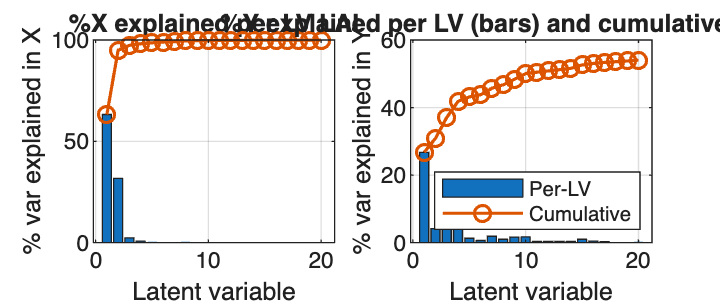

cumY = cumsum(100*PCTVAR(2,1:ncomp));
cumX = cumsum(100*PCTVAR(1,1:ncomp));
figure('Name','Explained Variance','Position',[100 100 900 380]);
subplot(1,2,1)
bar(1:ncomp, 100*PCTVAR(1,1:ncomp)); hold on
plot(1:ncomp, cumX, 'o-', 'LineWidth', 1.2); hold off
xlabel('Latent variable'); ylabel('% var explained in X');
title("%X explained per LV "+sel); grid on
subplot(1,2,2)
bar(1:ncomp, 100*PCTVAR(2,1:ncomp)); hold on
plot(1:ncomp, cumY, 'o-','LineWidth',1.2); hold off
xlabel('Latent variable'); ylabel('% var explained in Y');
title("%Y explained per LV (bars) and cumulative (line) "+sel); grid on
legend({'Per-LV','Cumulative'},'Location','southeast');

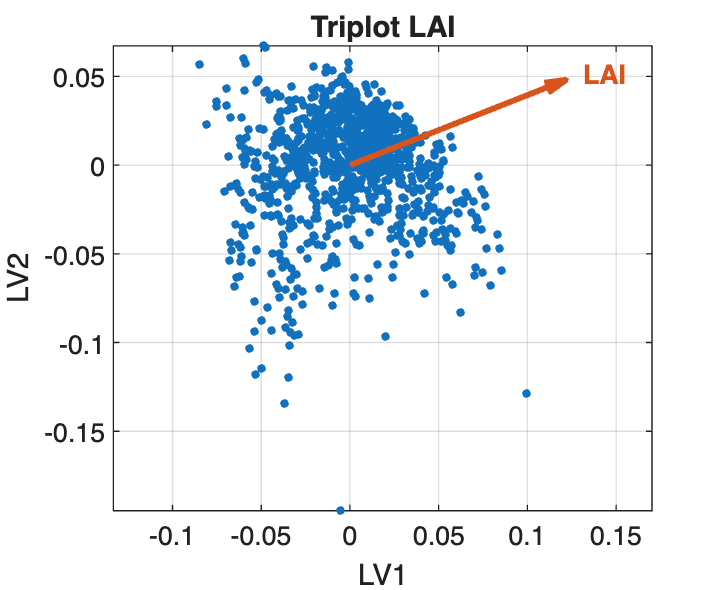


S  = XS(:,1:2);         
Lx = XL(:,1:2);         
Ly = YL(1:2)';          

% Normalize loadings to unit length: this is just for visu. 
Lx_unit = Lx ./ max(vecnorm(Lx,2,2), eps);   
Ly_unit = Ly ./ max(norm(Ly), eps);

% radius
sRange = max([range(S(:,1)), range(S(:,2))]);
R = 0.5 * sRange;  

xColor = [0.00 0.45 0.74];  
yColor = [0.85 0.33 0.10];   


figure('Name','PLS Triplot','Position',[100 100 780 640]); 
hold on; box on; grid on

% Scores with gradient color
scatter(S(:,1), S(:,2), 10, 'filled'); 
quiver(0,0, R*Ly_unit(1), R*Ly_unit(2), 0, ...
    'LineWidth',2.2,'Color',yColor,'MaxHeadSize',0.3);
text(R*Ly_unit(1)*1.08, R*Ly_unit(2)*1.08, sel, ...
    'Color',yColor,'FontSize',10,'FontWeight','bold', Interpreter='none');
xlabel('LV1'); ylabel('LV2'); axis equal
title("Triplot "+sel);
hold off

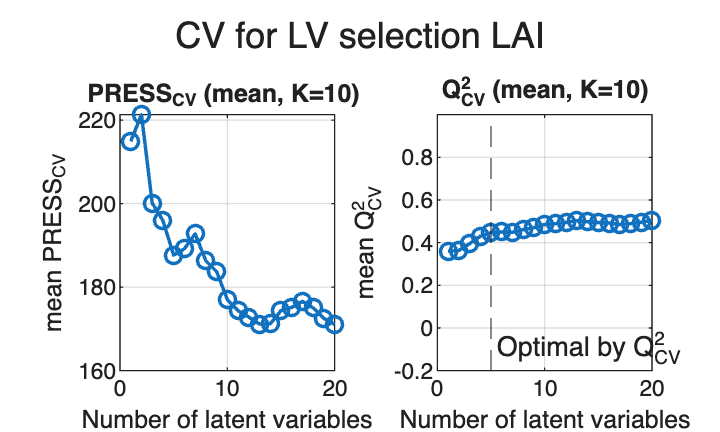

Kfold   = 10; 
nTrain  = size(Xtr,1);
block   = floor(nTrain/(Kfold+1));
maxLV   = ncomp;

foldInfo = struct('calIdx',[],'valIdx',[]);
for f = 1:Kfold
    calEnd = block*f;
    valBeg = calEnd + 1;
    valEnd = min(calEnd + block, nTrain);
    if valBeg > nTrain, break; end
    foldInfo(f).calIdx = 1:calEnd;
    foldInfo(f).valIdx = valBeg:valEnd;
end
Keff = sum(~arrayfun(@(s) isempty(s.valIdx), foldInfo));

PRESS_folds = nan(Keff, maxLV);
Q2_folds    = nan(Keff, maxLV);
for a = 1:maxLV
    for f = 1:Keff
        Ci = foldInfo(f).calIdx;
        Vi = foldInfo(f).valIdx;
        if normalize
            muC=mean(Ytr(Ci));
            sdC=std(Ytr(Ci));
            yc = (Ytr(Ci)-muC)./sdC;
            yv = (Ytr(Vi)-muC)./sdC;
        else
            yc = Ytr(Ci);
            yv = Ytr(Vi);
        end
        Xc = Xtr(Ci,:);  
        Xv = Xtr(Vi,:);  
        
        
 
        % Rank minus 1 cause of normalization
        r = min([a, rank(Xc)-1, size(Xc,2)]);
        [~,~,~,~,BETA] = plsregress(Xc, yc, r);

        yhat_v = [ones(size(Xv,1),1) Xv]*BETA;

        press_f = sum((yv - yhat_v).^2);
        ybar_cal = mean(yc);
        tss_f   = sum((yv - ybar_cal).^2);

        PRESS_folds(f,a) = press_f;
        Q2_folds(f,a)    = 1 - press_f / max(tss_f, eps);  
    end
end

PRESS_med = mean(PRESS_folds, 1, 'omitnan');
Q2_med    = mean(Q2_folds,    1, 'omitnan');

% 

%% Plots: mean curves (and optional fold distributions)
figure("Name","CV sel"+sel);
subplot(1,2,1)
plot(1:maxLV, PRESS_med, '-o','LineWidth',1.3); grid on
xlabel('Number of latent variables'); ylabel('mean PRESS_{CV}')
title(sprintf('PRESS_{CV} (mean, K=%d) ', Keff));

subplot(1,2,2)
plot(1:maxLV, Q2_med, '-o','LineWidth',1.3); grid on
xlabel('Number of latent variables'); ylabel('mean Q^{2}_{CV}')
title(sprintf('Q^{2}_{CV} (mean, K=%d)', Keff));
ylim([min(-0.2, min(Q2_med)-0.05) 1]);
xline(bestLVs(num),'--','Optimal by Q^{2}_{CV}','LabelOrientation','horizontal','LabelVerticalAlignment','bottom');

sgtitle("CV for LV selection "+sel);

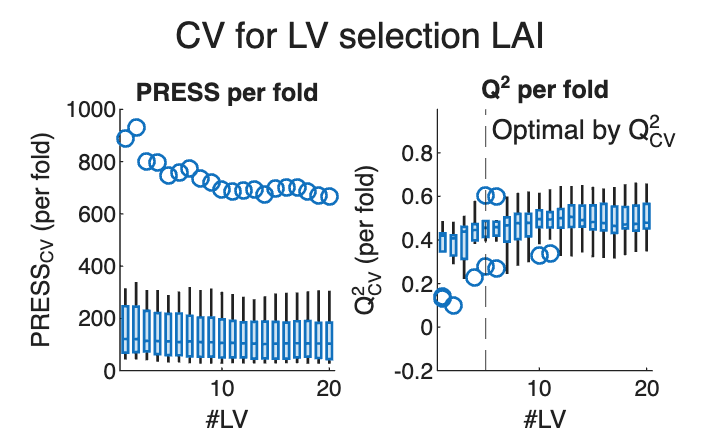

% see distributions across folds
figure();
subplot(1,2,1); boxchart(repelem(1:maxLV, Keff)', PRESS_folds(:));
xlabel('#LV'); ylabel('PRESS_{CV} (per fold)'); title("PRESS per fold")
subplot(1,2,2); boxchart(repelem(1:maxLV, Keff)', Q2_folds(:));
xlabel('#LV'); ylabel('Q^{2}_{CV} (per fold)'); title('Q^{2} per fold')
xline(bestLVs(num),'--','Optimal by Q^{2}_{CV}','LabelOrientation','horizontal','LabelVerticalAlignment','top');
ylim([-0.2 1]);
sgtitle("CV for LV selection "+sel);

% Fit the final model using the best LV 

bestLV = bestLVs(num);
[XL,yl,XS,YS,betaFinal,PCTVAR,MSE,stats] = plsregress(Xtr, Ytr, bestLV);

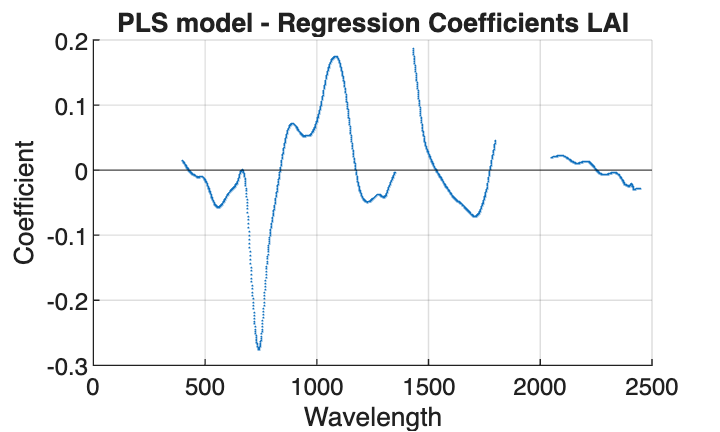

%Plot wavelength contribution
figure('Name',"PLS model - Regression Coefficients - "+sel);
scatter(wavelengths,betaFinal(2:end),4,'.'); yline(0,'k-'); grid on
xlabel("Wavelength")
ylabel('Coefficient'); title("PLS model - Regression Coefficients "+sel, Interpreter="none");

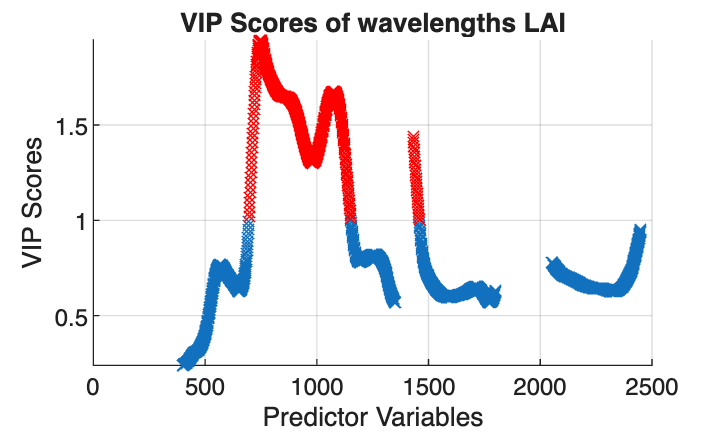


W0 = stats.W ./ sqrt(sum(stats.W.^2,1));
%Calculate the VIP scores for ncomp components.

p = size(XL,1);
sumSq = sum(XS.^2,1).*sum(yl.^2,1);
vipScore = sqrt(p* sum(sumSq.*(W0.^2),2) ./ sum(sumSq,2));
%Find variables with a VIP score greater than or equal to 1.
indVIP = find(vipScore >= 1);
%Plot VIP score
scatter(wavelengths,vipScore,"x")
hold on
scatter(wavelengths(indVIP),vipScore(indVIP),"rx")
grid on
hold off
axis tight
xlabel("Predictor Variables")
ylabel("VIP Scores")
title("VIP Scores of wavelengths "+sel, Interpreter="none")
xlim([0 2500])

% Calculate PRESS and Q2

yhat = [ones(size(Xte,1),1) Xte]*betaFinal;

press_final = sum((Yte - yhat).^2)

press_final = 456.9972

ybar_cal_f = mean(Ytr);
tss_final   = sum((Ytr - ybar_cal_f).^2);
rmseF=rmse(Yte,yhat)

rmseF = 1.1732

nrmse=rmseF/std(Yte)

nrmse = 0.7311

Q2_final    = 1 - press_final / max(tss_final, eps) 

Q2_final = 0.8359

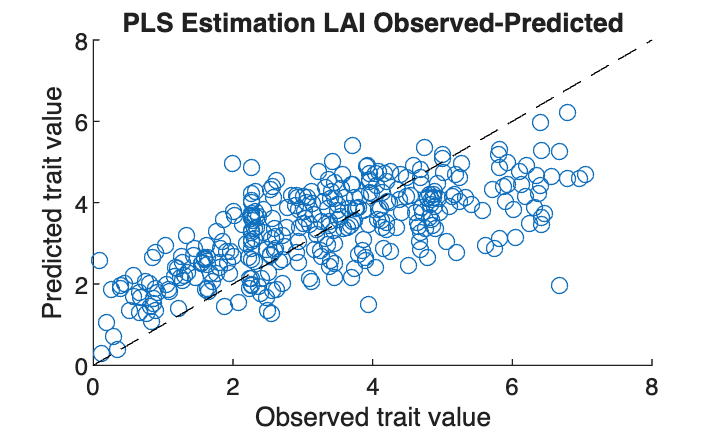


figure;
scatter(Yte,yhat)
title("PLS Estimation "+sel+" Observed-Predicted")
hold on 
plot(xlim,xlim, "k--")
hold off
xlabel("Observed trait value")
ylabel("Predicted trait value")